clear;
clc;


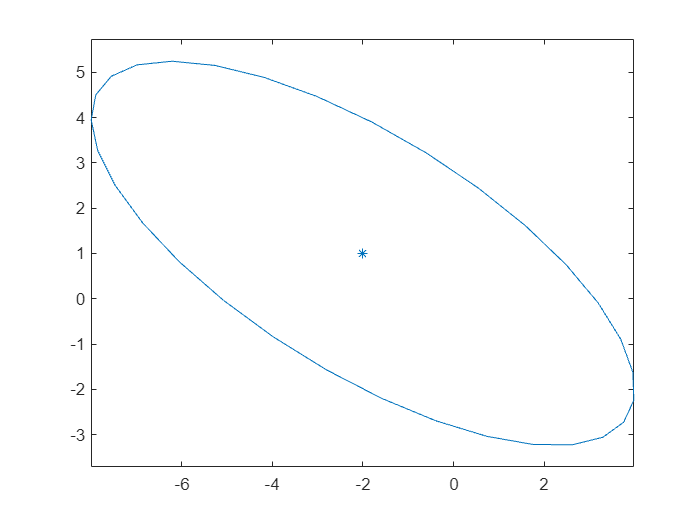

%Here we give parameters for a Gaussian density. The parameter mu is the mean, and P is the covariance matrix.
mu = [-2; 1];
P = [4, -2; -2 2];

%Call your function.
xy = sigmaEllipse2D(mu, P);

%Now plot the generated points. You should see an elongated ellipse stretching from the top left corner to the bottom right. 
figure(1);
h1 = plot(xy(1,:), xy(2,:));
%Set the scale of x and y axis to be the same. This should be done if the two variables are in the same domain, e.g. both are measured in meters.
axis equal
hold on
%Also plot a star where the mean is, and make it have the same color as the ellipse.
plot(mu(1), mu(2), '*', 'color', h1.Color);

function [ xy ] = sigmaEllipse2D( mu, Sigma, level, npoints )
%SIGMAELLIPSE2D generates x,y-points which lie on the ellipse describing
% a sigma level in the Gaussian density defined by mean and covariance.
%
%Input:
%   MU          [2 x 1] Mean of the Gaussian density
%   SIGMA       [2 x 2] Covariance matrix of the Gaussian density
%   LEVEL       Which sigma level curve to plot. Can take any positive value, 
%               but common choices are 1, 2 or 3. Default = 3.
%   NPOINTS     Number of points on the ellipse to generate. Default = 32.
%
%Output:
%   XY          [2 x npoints] matrix. First row holds x-coordinates, second
%               row holds the y-coordinates. First and last columns should 
%               be the same point, to create a closed curve.


%Setting default values, in case only mu and Sigma are specified.
if nargin < 3
    level = 3;
end
if nargin < 4
    npoints = 32;
end

%Your code here
phi = linspace(0,2*pi,npoints);
cov=sqrtm(Sigma);
z=level*[cos(phi);sin(phi)];
xy=mu+cov*z;
end